%Import Table 1: Observed shots
observed = [.75 .1 -1;
            .85 .8 -1;
            .85 .95 1;
            .15 .1 -1;
            .05 .25 1;
            .05 .5 1;
            .85 .25 -1];
len = size(observed,1);

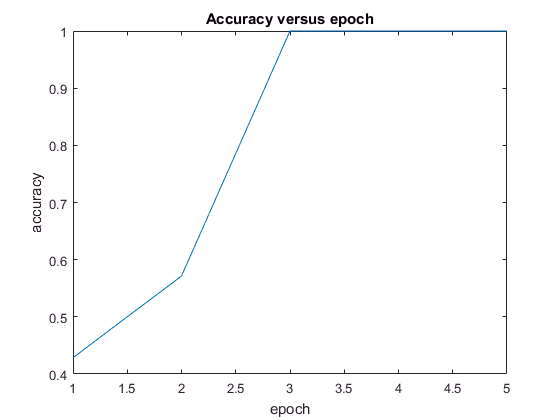

%%Perceptron function for data set
%Perceptron initializations
epochs = 5;
w = double(zeros(1,2));
acc = double(ones(1,epochs));
%Quick perceptron algorithm
for i = 1:epochs
    for j = 1:len
        val = observed(j,3)*dot((w.'),observed(j,1:2));
        if val <= 0
            w = w + observed(j,3).*observed(j,1:2);
            acc(i) = acc(i) - 1/len;
        end
    end
end
%Plotting accuracy
plot(acc)
title('Accuracy versus epoch');
xlabel('epoch'); ylabel('accuracy');

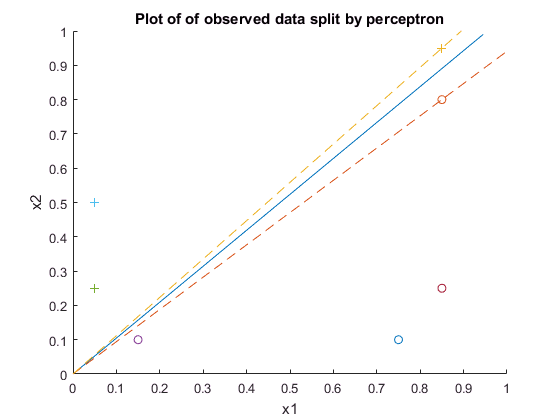

%Plotting scatter of data with decision boundary
figure;
hold on;
for i = 1:len
    if observed(i,3) == 1
        scatter(observed(i,1),observed(i,2),'+');
    else
        scatter(observed(i,1),observed(i,2),'o');
    end
end
s = 0.9;
plot([0 -s*w(1)],[0 s*w(2)]);
plot([0 1],[0 (0.8/0.85)],'--',[0 1],[0 (0.95/0.85)],'--')
title('Plot of of observed data split by perceptron');
xlabel('x1'); ylabel('x2'); axis([0 1 0 1]);
hold off;

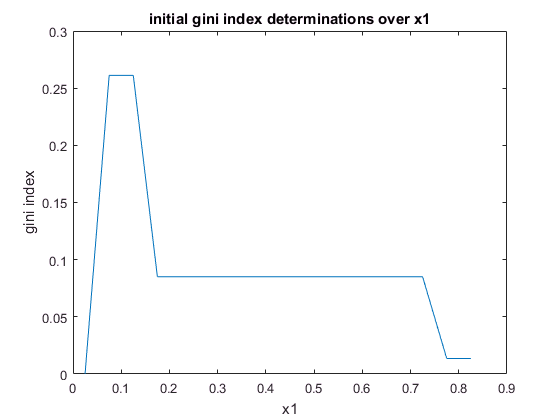

%%Full grown decision tree with Gini index
%Initializations involving start and end values and resolution
r1 = 0;
r2 = 1;
res = 20;
%evaluate gini index values
evaluation_1 = gindex(observed,20,0,1);

%Plot gini index values found for each 
range = r1 + double(r2 - r1)/( 2 * res) : double(r2 - r1)/res : r2;
plot(range,evaluation_1(:,1))
xlabel('x1'); ylabel('gini index');
title('initial gini index determinations over x1');

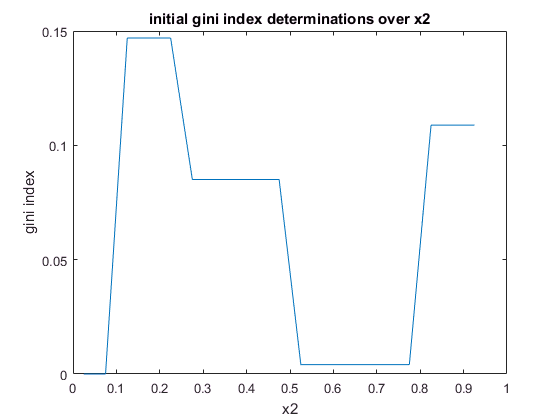

plot(range,evaluation_1(:,2))
xlabel('x2'); ylabel('gini index');
title('initial gini index determinations over x2');

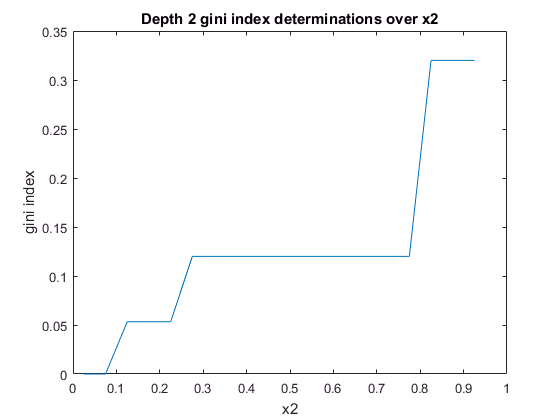


%Removing values from data set which were removed from initial split
a = observed;
rem = find( a(:,1) < 0.1 );
a(rem,:) = [];
a(:,1) = [];

%Depth 2 gini index values
evaluation_2 = gindex(a,20,0,1);
plot(range,evaluation_2(:,1))
xlabel('x2'); ylabel('gini index');
title('Depth 2 gini index determinations over x2');


%Plotting scatter of data with decision boundary
figure;
hold on;
for i = 1:len
    if observed(i,3) == 1
        scatter(observed(i,1),observed(i,2),'+');
    else
        scatter(observed(i,1),observed(i,2),'o');
    end
end
s = 0.9

s = 0.9000

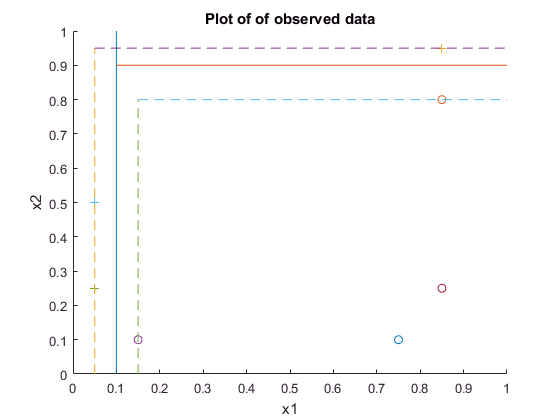

plot([0.1 0.1],[0 1.0],[0.1 1.0],[0.9 0.9]);
title('Plot of of observed data'); xlabel('x1'); ylabel('x2');
plot([0.05 0.05],[0 0.95],'--',[0.05 1],[0.95 0.95],'--');
plot([0.15 0.15],[0 0.8],'--',[0.15 1],[0.8 0.8],'--');
hold off;

%%Determining an optimal decision boundary that passes through the origin
%Set up resolution and test values for 
res = 100;
poss = 1.20:.005:1.70;
best_acc = double(zeros(1,2));

%Tests a logarithmic range of boundary x1=s*x2 values for s
for i = 1:res
    curr_acc = 1.0;
    for j = 1:res
        %a is actual value, b is value based on current boundary test
        a = sqrt(double(j/res));
        if poss(i)*double(j/res) > 1
            b = 1;
        else
            b = poss(i)*double(j/res);
        end
        %Determines estimated accuracy across x1 = [0 1]
        curr_acc = curr_acc - abs(a - b)/double(res);
    end    
    if curr_acc > best_acc(1)
        %Search for best accuracy for all boundary values
        best_acc = [curr_acc poss(i)];
    end
end
best_acc

best_acc =     0.9026    1.4150


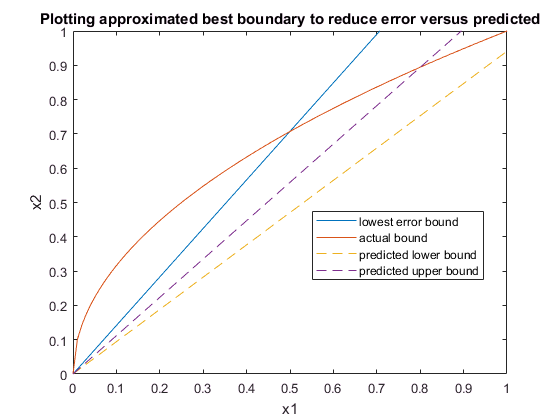


%Plotting bounding and actual values
x1 = 0:0.01:1;
x2_bound = x1*best_acc(2);
x2_act = sqrt(x1);
figure;
plot(x1,x2_bound,x1,x2_act);
hold on;
plot([0 1],[0 (0.8/0.85)],'--',[0 1],[0 (0.95/0.85)],'--')
title('Plotting approximated best boundary to reduce error versus predicted')
axis([0 1 0 1]); xlabel('x1'); ylabel('x2');
legend('lowest error bound','actual bound','predicted lower bound','predicted upper bound','location','best');
hold off;

%%Determine optimal 2 depth tree with a vertical split
res = 20;
area = 50;
best_acc = double(zeros(1,4));
best_acc(1) = double(1/3);
ver_s1 = 0.20:.002:0.24;
ver_s2 = 0.33:.002:0.37;
ver_s3 = 0.77:.002:0.81;

for i = 1:res
    for j = 1:res
        for k = 1:res
            curr_acc = 1.0;
            for l = 1:area
                a = sqrt(double(l/area));
                if ver_s1(i) > double(l/area)
                    b = ver_s2(j);
                else
                    b = ver_s3(k);
                end
                curr_acc = curr_acc - abs(a - b)/double(area);
            end
            if curr_acc > best_acc(1)
                %Search for best accuracy for all boundary values
                best_acc = [curr_acc ver_s1(i) ver_s2(j) ver_s3(k)];
            end
        end
    end
end

best_acc

best_acc =     0.8822    0.2220    0.3460    0.7880


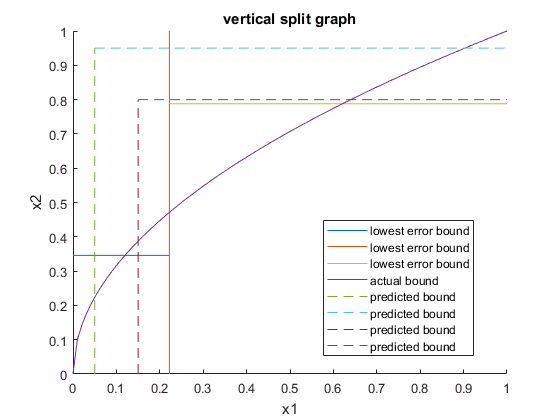

figure; hold on;
plot([0 best_acc(2)],[best_acc(3) best_acc(3)],[best_acc(2) best_acc(2)],[0 1],[best_acc(2) 1],[best_acc(4) best_acc(4)])
plot(x1,x2_act);
plot([0.05 0.05],[0 0.95],'--',[0.05 1],[0.95 0.95],'--');
plot([0.15 0.15],[0 0.8],'--',[0.15 1],[0.8 0.8],'--');
axis([0 1 0 1]); xlabel('x1'); ylabel('x2'); title('vertical split graph');
legend('lowest error bound','lowest error bound','lowest error bound','actual bound','predicted bound','predicted bound','predicted bound','predicted bound','location','best');
hold off;

%%Determine optimal 2 depth tree with a horizontal split
res = 20;
area = 50;
best_acc = double(zeros(1,4));
best_acc(1) = double(1/3);
ver_s1 = 0.6:.002:0.64;
ver_s2 = 0.07:.002:0.11;
ver_s3 = 0.63:.002:0.67;

for i = 1:res
    for j = 1:res
        for k = 1:res
            curr_acc = 1.0;
            for l = 1:area
                a = sqrt(double(l/area));
                if ver_s2(j) > double(l/area)
                    b = 0;
                elseif ver_s3(k) < double(l/area)
                    b = 1;
                else
                    b = ver_s1(i);
                end
                curr_acc = curr_acc - abs(a - b)/double(area);
            end
            if curr_acc > best_acc(1)
                %Search for best accuracy for all boundary values
                best_acc = [curr_acc ver_s1(i) ver_s2(j) ver_s3(k)];
            end
        end
    end
end

best_acc

best_acc =     0.8827    0.6140    0.0820    0.6500


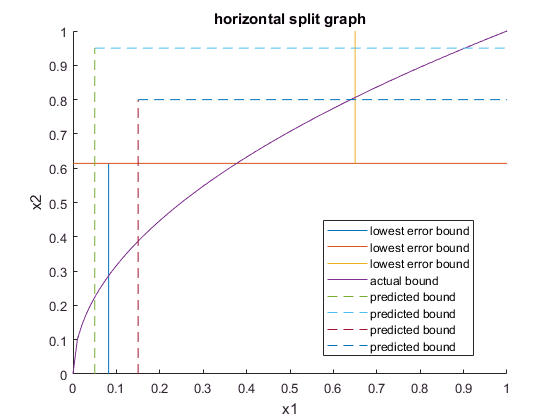

figure; hold on;
plot([best_acc(3) best_acc(3)],[0 best_acc(2)],[0 1],[best_acc(2) best_acc(2)],[best_acc(4) best_acc(4)],[best_acc(2) 1])
plot(x1,x2_act);
plot([0.05 0.05],[0 0.95],'--',[0.05 1],[0.95 0.95],'--');
plot([0.15 0.15],[0 0.8],'--',[0.15 1],[0.8 0.8],'--');
axis([0 1 0 1]); xlabel('x1'); ylabel('x2');title('horizontal split graph');
legend('lowest error bound','lowest error bound','lowest error bound','actual bound','predicted bound','predicted bound','predicted bound','predicted bound','location','best');
hold off;

%%Best decision bound with transformed input
res = 200;
poss = logspace(-.5,.5,res);
acc_transformed_perc = double(zeros(1,2));

for i = 1:res
    curr_acc = 1.0;
    for j = 1:res
        a = sqrt(double(j/res));
        %Transformed x1 input represented by sqrt(double(j/res))
        if poss(i)*sqrt(double(j/res)) > 1
            b = 1;
        else
            %Again, our x1 is transformed
            b = poss(i)*sqrt(double(j/res));
        end
        %Determines estimated accuracy across x1 = [0 1]
        curr_acc = curr_acc - abs(a - b)/double(res);
    end    
    if curr_acc > acc_transformed_perc(1)
        %Search for best accuracy for all boundary values
        acc_transformed_perc = [curr_acc poss(i)];
    end
end
acc_transformed_perc

acc_transformed_perc =     0.9962    1.0058


%%Determine optimal 2 depth tree
res = 50;
acc_transformed_tree = double(zeros(1,3));
acc_transformed_tree(1) = double(1/3);

for i = 1:res
    for j = 1:res
        curr_acc = 1.0;
        for k = 1:res
            a = sqrt(double(k/res));
            %Uses a transformed input value to repesent x1
            if double(i/res) > sqrt(double(k/res))
                b = 0;
            else
                b = double(j/res);
            end
            curr_acc = curr_acc - abs(a - b)/double(res);
        end
        if curr_acc > acc_transformed_tree(1)
            %Search for best accuracy for all boundary values
            acc_transformed_tree = [curr_acc double(i/res) double(j/res)];
        end
    end
end
acc_transformed_tree

acc_transformed_tree =     0.8355    0.3800    0.7600


%%Determine optimal perceptron for classifying the paint
res = 100;
poss = logspace(-1,1,res);
acc_paint_perc = double(zeros(1,2));

for i = 1:res
    curr_acc = 1.0;
    for j = 1:res
        %Set up boundary for paint by setting 'a' to matching paint values
        if double(j/res) < 0.5
            a = 0;
        else
            a = 0.25;
        end
        
        if poss(i)*double(j/res) > 1
            b = 1;
        else
            b = poss(i)*double(j/res);
        end
        curr_acc = curr_acc - abs(a - b)/double(res);
    end    
    if curr_acc > acc_paint_perc(1)
        %Search for best accuracy for all boundary values
        acc_paint_perc = [curr_acc poss(i)];
    end
end
acc_paint_perc

acc_paint_perc =     0.9420    0.2915


%%Determine optimal 2 depth tree for classifying paint
res = 50;
acc_paint_tree = double(zeros(1,3));
%Initialized at accuracy for (zero,zero);
acc_paint_tree(1) = double(7/8);

for i = 1:res
    for j = 1:res
        curr_acc = 1.0;
        for k = 1:res
            %Set up same boundary for a
            if double(k/res) < 0.5
                a = 0;
            else
                a = 0.25;
            end            
            
            %Uses a transformed input value to repesent x1
            if double(i/res) > double(k/res)
                b = 0;
            else
                b = double(j/res);
            end
            curr_acc = curr_acc - abs(a - b)/double(res);

        end
        if curr_acc > acc_paint_tree(1)
            %Search for best accuracy for all boundary values
            acc_paint_tree = [curr_acc double(i/res) double(j/res)];
        end
    end
end
acc_paint_tree

acc_paint_tree =     0.9948    0.5000    0.2400
